clear ur
ur = urRTDEClient('192.168.1.10','CobotName','universalUR5e') %Conectamos ROS de matlab con el cobot

ur =   urRTDEClient with properties:

            CobotName: 'universalUR5e'
       URControllerIP: '192.168.1.10'
    ControllerVersion: '5.22.0.0'
        RTDEFrequency: 125
    ConnectionTimeOut: 10
        RigidBodyTree: [1×1 rigidBodyTree]


jointAngles = readJointConfiguration(ur) %Lee los angulos del brazo

jointAngles =     1.5708   -1.5708    1.5708   -1.5708   -1.5708         0


defase_Robot = pi;
realSense = realsenseSubscriberSO_ARM2; %-----------ACTIVAR
% Carga la tabla desde el archivo MAT
load('mi_tabla.mat','TablaDatos');

d = load("detector_hotel1.mat");
detector = d.detector

detector =   yolov4ObjectDetector with properties:

             Network: [1×1 dlnetwork]
         AnchorBoxes: {2×1 cell}
          ClassNames: {5×1 cell}
           InputSize: [416 416 3]
    PredictedBoxType: 'axis-aligned'
           ModelName: 'tiny-yolov4-coco'


### ***SECUENCIA 1 (GRIS)***

for i=1:1:8 
    actuateGripper(ur,'release')
    %Secuencia de colocarse sobre el objeto e ir por el
    n = 0.300;
    coci = car2pol(0.05,0.35,0.35);
    jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
    pause(2.5)
    for e=1:1:4
        coci = car2pol(TablaDatos.X(i),TablaDatos.Y(i),TablaDatos.Z(i)+n);
        jointAngles = MoverRobot(coci,TablaDatos.Angulo_gripper(i),defase_Robot,jointAngles,ur); %ur
        pause(0.25)
        n = n-0.100;
    end

    %Cierra el gripper
    actuateGripper(ur,'grip');
    pause(3);
    if ismember(TablaDatos.Etiqueta(i),["Azul", "Morado", "Verde","Rojo"])
        coci = car2pol(0.1,0.35,0.35);
        jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
        pause(2.5)
        jointAngles=sube(coci,jointAngles,defase_Robot,ur);
        [jointAngles,coci]=bascula(coci,0,defase_Robot,jointAngles,ur,realSense);
        %Toma de fotos para analisis de color
        % [rgb, ~, ~]=realSense.step;
        % colorLabel = detectar_color(rgb);
        % [bandera] = bandera_botes_brasil(label)
        %
    end
    %Va al bote de basura
    pause(2.5)
    jointAngles = sube(coci,jointAngles,defase_Robot,ur);
    pause(2.5)

    if i>=4 && i<=5
        coci = car2pol(0.18,0.3,0.335);
        jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
        pause(2.5)
    end 

    [jointAngles,~]=bote(0,defase_Robot,jointAngles,ur,TablaDatos.Cesto(i));
    pause(2.5);
end

condicion = logical
   1


q =     1.0423
   -1.9577
    1.8136
   -1.4267
   -1.5708
   -0.3858


condicion = 1×2 logical array
   1   0


q =     1.8580
   -1.6346
    0.9574
   -0.8936
   -1.5708
    1.2320


condicion = 1×2 logical array
   1   0


q =     1.8580
   -1.7663
    1.3656
   -1.1701
   -1.5708
    1.2320


condicion = 1×2 logical array
   1   0


q =     1.8580
   -1.8305
    1.6791
   -1.4194
   -1.5708
    1.2320


condicion = 1×2 logical array
   1   0


q =     1.8580
   -1.8364
    1.9391
   -1.6735
   -1.5708
    1.2320


condicion = 1×2 logical array
   1   0


q =     1.8580
   -1.8412
    1.8658
   -1.5954
   -1.5708
    1.2320


condicion = 1×2 logical array
   1   0


q =     1.8090
   -1.9292
    1.8350
   -1.4766
   -1.5708
    1.1982


condicion = 1×2 logical array
   1   0


q =     2.7763
   -1.5112
    1.5733
   -1.6329
   -1.5708
    1.3182


condicion = logical
   1


q =     1.0423
   -1.9577
    1.8136
   -1.4267
   -1.5708
   -0.3858


condicion = 1×2 logical array
   1   0


q =     1.7304
   -1.2465
    1.0410
   -1.3652
   -1.5708
    0.9733


condicion = 1×2 logical array
   1   0


q =     1.7304
   -1.2654
    1.3226
   -1.6280
   -1.5708
    0.9733


condicion = 1×2 logical array
   1   0


q =     1.7304
   -1.2229
    1.5248
   -1.8728
   -1.5708
    0.9733


condicion = 1×2 logical array
   1   0


q =     1.7304
   -1.1269
    1.6647
   -2.1086
   -1.5708
    0.9733


condicion = 1×2 logical array
   1   0


q =     1.7304
   -1.2669
    1.2812
   -1.5851
   -1.5708
    1.3587


condicion = 1×2 logical array
   1   0


q =     1.8090
   -1.9292
    1.8350
   -1.4766
   -1.5708
    1.1982


condicion = 1×2 logical array
   1   0


q =     2.7763
   -1.5112
    1.5733
   -1.6329
   -1.5708
    1.3182


condicion = logical
   1


q =     1.0423
   -1.9577
    1.8136
   -1.4267
   -1.5708
   -0.3858


condicion = 1×2 logical array
   1   0


q =     1.7944
   -1.1040
    0.9185
   -1.3852
   -1.5708
    0.9908


condicion = 1×2 logical array
   1   0


q =     1.7944
   -1.1186
    1.1962
   -1.6484
   -1.5708
    0.9908


condicion = 1×2 logical array
   1   0


q =     1.7944
   -1.0710
    1.3849
   -1.8847
   -1.5708
    0.9908


condicion = 1×2 logical array
   1   0


q =     1.7944
   -0.9734
    1.5071
   -2.1044
   -1.5708
    0.9908


condicion = 1×2 logical array
   1   0


q =     1.7944
   -1.1207
    1.0768
   -1.5269
   -1.5708
    1.3762


condicion = 1×2 logical array
   1   0


q =     1.8090
   -1.9292
    1.8350
   -1.4766
   -1.5708
    1.1982


condicion = 1×2 logical array
   1   0


q =     2.3353
   -1.2481
    1.2561
   -1.5788
   -1.5708
    1.3612


condicion = logical
   1


q =     1.0423
   -1.9577
    1.8136
   -1.4267
   -1.5708
   -0.3858


condicion = logical
   1


q =    -0.1911
   -1.8593
    1.3464
   -1.0579
   -1.5708
    1.1767


condicion = logical
   1


q =    -0.1911
   -1.9493
    1.6783
   -1.2998
   -1.5708
    1.1767


condicion = logical
   1


q =    -0.1911
   -1.9855
    1.9576
   -1.5429
   -1.5708
    1.1767


condicion = logical
   1


q =    -0.1911
   -1.9568
    2.1984
   -1.8124
   -1.5708
    1.1767


condicion = logical
   1


q = 6×1
   -0.1911
   -1.9855
    1.9576
   -1.5429
   -1.5708
    1.1767


condicion = logical
   1


q = 6×1
    0.6395
   -1.9721
    1.8605
   -1.4593
   -1.5708
   -0.3901


condicion = 1×2 logical array
   1   0


q = 6×1
    1.8090
   -1.9292
    1.8350
   -1.4766
   -1.5708
    1.1982


condicion = 1×2 logical array
   1   0


q = 6×1
    2.7763
   -1.5112
    1.5733
   -1.6329
   -1.5708
    1.3182


condicion = logical
   1


q = 6×1
    1.0423
   -1.9577
    1.8136
   -1.4267
   -1.5708
   -0.3858


condicion = logical
   1


q = 6×1
   -0.1911
   -1.9554
    1.7083
   -1.3236
   -1.5708
    1.1767


condicion = logical
   1


q = 6×1
   -0.1911
   -1.9859
    1.9833
   -1.5683
   -1.5708
    1.1767


condicion = logical
   1


q = 6×1
   -0.1911
   -1.9493
    2.2204
   -1.8419
   -1.5708
    1.1767


condicion = logical
   1


q = 6×1
   -0.1911
   -1.8133
    2.4170
   -2.1746
   -1.5708
    1.1767


condicion = logical
   1


q = 6×1
   -0.1911
   -1.9855
    1.9576
   -1.5429
   -1.5708
    1.1767


condicion = logical
   1


q = 6×1
    0.6395
   -1.9721
    1.8605
   -1.4593
   -1.5708
   -0.3901


condicion = 1×2 logical array
   1   0


q = 6×1
    1.8090
   -1.9292
    1.8350
   -1.4766
   -1.5708
    1.1982


condicion = 1×2 logical array
   1   0


q = 6×1
    2.7763
   -1.5112
    1.5733
   -1.6329
   -1.5708
    1.3182


condicion = logical
   1


q = 6×1
    1.0423
   -1.9577
    1.8136
   -1.4267
   -1.5708
   -0.3858


condicion = logical
   1


q = 6×1
   -0.4747
   -1.9545
    1.7548
   -1.3711
   -1.5708
   -0.6892


condicion = logical
   1


q = 6×1
   -0.4747
   -1.9731
    2.0220
   -1.6197
   -1.5708
   -0.6892


condicion = logical
   1


q = 6×1
   -0.4747
   -1.9205
    2.2513
   -1.9016
   -1.5708
   -0.6892


condicion = logical
   1


q = 6×1
   -0.4747
   -1.7617
    2.4377
   -2.2468
   -1.5708
   -0.6892


condicion = logical
   1


q = 6×1
    0.9176
   -1.9308
    1.7974
   -1.4375
   -1.5708
   -0.3741


condicion = logical
   1


q = 6×1
    0.9176
   -1.9395
    1.9307
   -1.5620
   -1.5708
    1.1959


condicion = logical
   1


q = 6×1
    1.4205
   -1.4402
    1.3674
   -1.4980
   -1.5708
    1.3314


condicion = logical
   1


q = 6×1
    1.4205
   -1.4274
    1.6088
   -1.7522
   -1.5708
    1.3314


condicion = logical
   1


q = 6×1
    1.4205
   -1.3554
    1.7904
   -2.0058
   -1.5708
    1.3314


condicion = logical
   1


q = 6×1
    1.4205
   -1.2246
    1.9154
   -2.2616
   -1.5708
    1.3314


condicion = logical
   1


q = 6×1
    1.4205
   -1.4413
    1.4962
   -1.6257
   -1.5708
    1.3314


condicion = 1×2 logical array
   1   0


q = 6×1
    1.8090
   -1.9292
    1.8350
   -1.4766
   -1.5708
    1.1982


condicion = 1×2 logical array
   1   0


q = 6×1
    2.3353
   -1.2481
    1.2561
   -1.5788
   -1.5708
    1.3612


condicion = logical
   1


q = 6×1
    1.0423
   -1.9577
    1.8136
   -1.4267
   -1.5708
   -0.3858


condicion = logical
   1


q = 6×1
   -0.4747
   -1.9647
    1.8254
   -1.4315
   -1.5708
   -0.6892


condicion = logical
   1


q = 6×1
   -0.4747
   -1.9677
    2.0829
   -1.6859
   -1.5708
   -0.6892


condicion = logical
   1


q = 6×1
   -0.4747
   -1.8926
    2.3024
   -1.9807
   -1.5708
   -0.6892


condicion = logical
   1


q = 6×1
   -0.4747
   -1.7000
    2.4755
   -2.3463
   -1.5708
   -0.6892


condicion = logical
   1


q = 6×1
    0.9176
   -1.9308
    1.7974
   -1.4375
   -1.5708
   -0.3741


condicion = logical
   1


q = 6×1
    0.9176
   -1.9395
    1.9307
   -1.5620
   -1.5708
    1.1959


condicion = logical
   1


q = 6×1
    1.4205
   -1.4402
    1.3674
   -1.4980
   -1.5708
    1.3314


condicion = logical
   1


q = 6×1
    1.4205
   -1.4274
    1.6088
   -1.7522
   -1.5708
    1.3314


condicion = logical
   1


q = 6×1
    1.4205
   -1.3554
    1.7904
   -2.0058
   -1.5708
    1.3314


condicion = logical
   1


q = 6×1
    1.4205
   -1.2246
    1.9154
   -2.2616
   -1.5708
    1.3314


condicion = logical
   1


q = 6×1
    1.4205
   -1.4413
    1.4962
   -1.6257
   -1.5708
    1.3314


condicion = 1×2 logical array
   1   0


q = 6×1
    1.8090
   -1.9292
    1.8350
   -1.4766
   -1.5708
    1.1982


condicion = 1×2 logical array
   1   0


q = 6×1
    2.7763
   -1.5112
    1.5733
   -1.6329
   -1.5708
    1.3182


condicion = logical
   1


q = 6×1
    1.0423
   -1.9577
    1.8136
   -1.4267
   -1.5708
   -0.3858


condicion = logical
   1


q = 6×1
   -0.4747
   -1.9713
    1.8934
   -1.4929
   -1.5708
   -0.6892


condicion = logical
   1


q = 6×1
   -0.4747
   -1.9575
    2.1414
   -1.7547
   -1.5708
   -0.6892


condicion = logical
   1


q = 6×1
   -0.4747
   -1.8573
    2.3508
   -2.0643
   -1.5708
   -0.6892


condicion = logical
   1


q = 6×1
   -0.4747
   -1.6283
    2.5088
   -2.4512
   -1.5708
   -0.6892


condicion = logical
   1


q = 6×1
    0.9176
   -1.9308
    1.7974
   -1.4375
   -1.5708
   -0.3741


condicion = logical
   1


q = 6×1
    0.9176
   -1.9395
    1.9307
   -1.5620
   -1.5708
    1.1959


condicion = logical
   1


q = 6×1
    1.4205
   -1.4402
    1.3674
   -1.4980
   -1.5708
    1.3314


condicion = logical
   1


q = 6×1
    1.4205
   -1.4274
    1.6088
   -1.7522
   -1.5708
    1.3314


condicion = logical
   1


q = 6×1
    1.4205
   -1.3554
    1.7904
   -2.0058
   -1.5708
    1.3314


condicion = logical
   1


q = 6×1
    1.4205
   -1.2246
    1.9154
   -2.2616
   -1.5708
    1.3314


condicion = logical
   1


q = 6×1
    1.4205
   -1.4413
    1.4962
   -1.6257
   -1.5708
    1.3314


condicion = 1×2 logical array
   1   0


q = 6×1
    1.8090
   -1.9292
    1.8350
   -1.4766
   -1.5708
    1.1982


condicion = 1×2 logical array
   1   0


q = 6×1
    2.3353
   -1.2481
    1.2561
   -1.5788
   -1.5708
    1.3612



coci = car2pol(0,0.35,0.35);
jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);

condicion = logical
   1


q = 6×1
    1.1801
   -1.9669
    1.8190
   -1.4228
   -1.5708
   -0.3899


### ***SECUENCIA 2 (AMARILLA)***

condicion = logical
   1


q = 6×1
    1.1801
   -1.9669
    1.8190
   -1.4228
   -1.5708
   -0.3899


condicion = logical
   1


q = 6×1
   -0.3909
   -2.4236
    2.0165
   -1.1636
   -1.5708
   -0.7610


ans = categorical
     Botella 


m = 3

label = "Botella"

condicion = logical
   1


q = 6×1
   -0.3909
   -2.2755
    1.6390
   -0.9342
   -1.5708
   -0.9430


condicion = logical
   1


q = 6×1
   -0.3909
   -2.4002
    1.9522
   -1.1228
   -1.5708
   -0.9430


condicion = logical
   1


q = 6×1
   -0.3909
   -2.4943
    2.2349
   -1.3114
   -1.5708
   -0.9430


condicion = logical
   1


q = 6×1
   -0.3909
   -2.5456
    2.4988
   -1.5241
   -1.5708
   -0.9430


condicion = logical
   1


q = 6×1
   -0.3909
   -2.4579
    2.1161
   -1.2291
   -1.5708
    0.8090


condicion = logical
   1


q = 6×1
    1.0423
   -1.8960
    1.5113
   -1.1861
   -1.5708
   -0.3858


condicion = 1×2 logical array
   1   0


q = 6×1
    1.8090
   -1.9292
    1.8350
   -1.4766
   -1.5708
    1.1982


condicion = 1×2 logical array
   1   0


q = 6×1
    2.3353
   -1.2481
    1.2561
   -1.5788
   -1.5708
    1.3612


condicion = logical
   1


q = 6×1
    1.0423
   -1.8960
    1.5113
   -1.1861
   -1.5708
   -0.3858


condicion = logical
   1


q = 6×1
    1.1801
   -1.9669
    1.8190
   -1.4228
   -1.5708
   -0.3899


condicion = 1×2 logical array
   1   0


q = 6×1
    1.0084
   -2.2483
    1.9806
   -1.3030
   -1.5708
   -0.5616


ans = categorical
     Botella 


m = 1

label = "Botella"

condicion = 1×2 logical array
   1   0


q = 6×1
    1.0084
   -2.2568
    2.0173
   -1.3313
   -1.5708
    0.6230


condicion = 1×2 logical array
   1   0


q = 6×1
    1.0084
   -2.2913
    2.2849
   -1.5644
   -1.5708
    0.6230


condicion = 1×2 logical array
   1   0


q = 6×1
    1.0084
   -2.2423
    2.5288
   -1.8573
   -1.5708
    0.6230


condicion = 1×2 logical array
   1   0


q = 6×1
    1.0084
   -2.0039
    2.7419
   -2.3087
   -1.5708
    0.6230


condicion = 1×2 logical array
   1   0


q = 6×1
    1.0084
   -2.2692
    2.0783
   -1.3799
   -1.5708
    1.0084


condicion = logical
   1


q = 6×1
    1.0423
   -1.8960
    1.5113
   -1.1861
   -1.5708
   -0.3858


condicion = 1×2 logical array
   1   0


q = 6×1
    1.8090
   -1.9292
    1.8350
   -1.4766
   -1.5708
    1.1982


condicion = 1×2 logical array
   1   0


q = 6×1
    2.3353
   -1.2481
    1.2561
   -1.5788
   -1.5708
    1.3612


condicion = logical
   1


q = 6×1
    1.0423
   -1.8960
    1.5113
   -1.1861
   -1.5708
   -0.3858


condicion = logical
   1


q = 6×1
    1.1801
   -1.9669
    1.8190
   -1.4228
   -1.5708
   -0.3899


condicion = 1×2 logical array
   1   0


q = 6×1
    1.4046
   -2.4475
    2.0188
   -1.1421
   -1.5708
   -0.7982


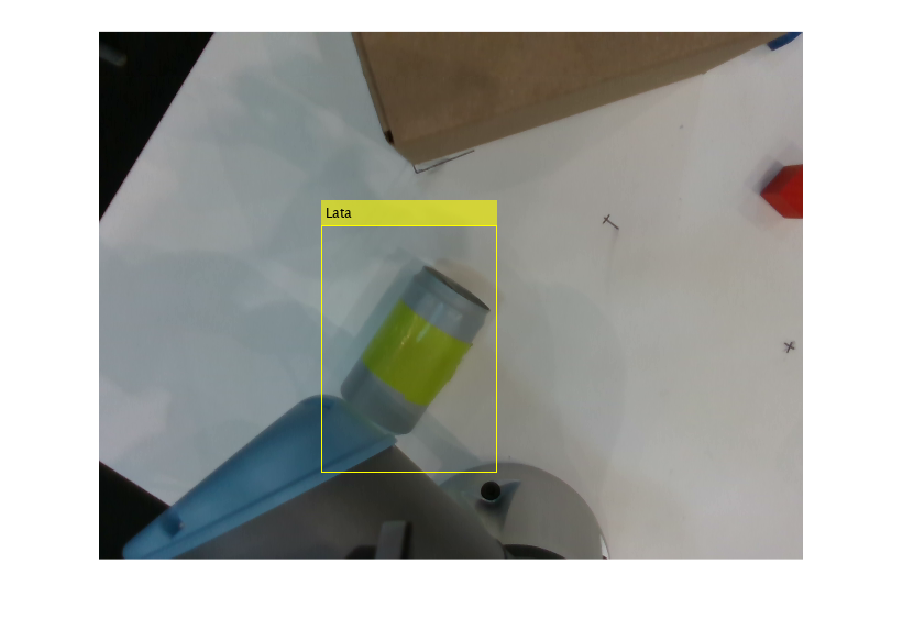


ans = 

  0×0 empty categorical array



m = 1

label = "Lata"

condicion = 1×2 logical array
   1   0


q = 6×1
    1.4046
   -2.4614
    2.0562
   -1.1656
   -1.5708
    0.3864


condicion = 1×2 logical array
   1   0


q = 6×1
    1.4046
   -2.5503
    2.3319
   -1.3524
   -1.5708
    0.3864


condicion = 1×2 logical array
   1   0


q = 6×1
    1.4046
   -2.5909
    2.5922
   -1.5721
   -1.5708
    0.3864


condicion = 1×2 logical array
   1   0


q = 6×1
    1.4046
   -2.4897
    2.8437
   -1.9247
   -1.5708
    0.3864


condicion = 1×2 logical array
   1   0


q = 6×1
    1.4046
   -2.4837
    2.1186
   -1.2056
   -1.5708
    0.7718


condicion = logical
   1


q = 6×1
    1.0423
   -1.8960
    1.5113
   -1.1861
   -1.5708
   -0.3858


condicion = 1×2 logical array
   1   0


q = 6×1
    1.8090
   -1.9292
    1.8350
   -1.4766
   -1.5708
    1.1982


condicion = 1×2 logical array
   1   0


q = 6×1
    2.3353
   -1.2481
    1.2561
   -1.5788
   -1.5708
    1.3612


condicion = logical
   1


q = 6×1
    1.0423
   -1.8960
    1.5113
   -1.1861
   -1.5708
   -0.3858


load('mi_tabla2.mat','TablaDatosAm');
for i=1:1:3
    %POSE INICIAL
    coci = car2pol(0,0.35,0.35);
    jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
    %ME COLOCO SOBRE UN OBJETO
    coci = car2pol(TablaDatosAm.X(i),TablaDatosAm.Y(i),0.335);
    jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
    %TOMO UNA FOTOGRAFIA 
    [rgb,~,~]=realSense.step;
    %APLICO RED NEURONAL
    [I,I2,bboxes,scores,labels] = fotos_brasil(rgb,detector);
    nombreArchivo = sprintf('fotoAmarilla2rgb_%03d.png', i);  % %03d asegura 3 dígitos (001, 002, ...)
    imwrite(I, nombreArchivo);
    nombreArchivo = sprintf('fotoAmarilla2det_%03d.png', i);  % %03d asegura 3 dígitos (001, 002, ...)
    imwrite(I2, nombreArchivo);
    imshow(I2)
    %%Habra que recortar la foto, tendría que ver un ejemplo para recortar
        %RED NEURONAL
        %ME DEBES DE DEVOLVER EN "label" EL NOMBRE DEL OBJETO
        Centroids = [bboxes(:,1)+bboxes(:,3)/2,bboxes(:,2)+bboxes(:,4)];

     
        temp = Centroids(:,1) > 240 & Centroids(:,1) < 390 & Centroids(:,2) > 200 & Centroids(:,2) < 400;
        Centroides = Centroids(temp,:);
        labels(temp)
        [~,m]=max(temp)
        label=string(labels(m))
     
    %SI ES LATA, ESTO; SI ES BOTELLA, ESTO
    if strcmp(label, 'Botella')
        %BAJO TANTOS CMS
        if i==1
            n = 0.300;
            for e=1:1:4
                coci = car2pol(TablaDatosAm.X(i),TablaDatosAm.Y(i),0.157+n);
                jointAngles = MoverRobot(coci,TablaDatosAm.Angulo_gripper(i),defase_Robot,jointAngles,ur); %ur
                pause(0.25)
                n = n-0.100;
            end
        else
            n = 0.300;
            for e=1:1:4
                coci = car2pol(TablaDatosAm.X(i),TablaDatosAm.Y(i),0.0220+n);
                jointAngles = MoverRobot(coci,TablaDatos.Angulo_gripper(i),defase_Robot,jointAngles,ur); %ur
                pause(0.25)
                n = n-0.100;
            end
        end
        %CIERRA GP
        actuateGripper(ur,'grip');
        pause(1)
        %SUBO
        jointAngles = sube(coci,jointAngles,defase_Robot,ur);
        pause(2.5)
        %MUEVO A PUNTO SEGURO
        coci = car2pol(0.05,0.35,0.45);
        jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
        pause(2.5)
        %VOY AL BOTE
        %ABRO GRIPPER
        [jointAngles,~]=bote(0,defase_Robot,jointAngles,ur,0);
        pause(2.5);
    elseif strcmp(label, 'Lata')
        %BAJO TANTOS CMS
        if i==1
            n = 0.300;
            for e=1:1:4
                coci = car2pol(TablaDatosAm.X(i),TablaDatosAm.Y(i),0.087+n);
                jointAngles = MoverRobot(coci,TablaDatosAm.Angulo_gripper(i),defase_Robot,jointAngles,ur); %ur
                pause(0.25)
                n = n-0.100;
            end
        else
            n = 0.300;
            for e=1:1:4
                coci = car2pol(TablaDatosAm.X(i),TablaDatosAm.Y(i),0.0220+n);
                jointAngles = MoverRobot(coci,TablaDatos.Angulo_gripper(i),defase_Robot,jointAngles,ur); %ur
                pause(0.25)
                n = n-0.100;
            end
        end
        %CIERRA GP
        actuateGripper(ur,'grip');
        pause(1)
        %SUBO A .335
        jointAngles = sube(coci,jointAngles,defase_Robot,ur);
        pause(2.5)
        %MUEVO A PUNTO SEGURO
        coci = car2pol(0.05,0.35,0.45);
        jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
        pause(2.5)
        %VOY AL BOTE
        %ABRO GRIPPER
        [jointAngles,~]=bote(0,defase_Robot,jointAngles,ur,0);
        pause(2.5);
    end
    %REGRESO A POSE SEGURA
    coci = car2pol(0.05,0.35,0.45);
    jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
    pause(2.5)
end


coci = car2pol(0,0.35,0.335);
jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
pause(2.5)

### ***SECUENCIA 3 (ROJA)***

load('mi_tabla3.mat','TablaDatosRo');
for i=1:1:12
    %POSE INICIAL
    coci = car2pol(0,0.35,0.35);
    jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
    %ME COLOCO SOBRE UN OBJETO
    coci = car2pol(TablaDatosRo.X(i),TablaDatosRo.Y(i),0.335);
    [jointAngles,H_actual] = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
    %TOMO UNA FOTOGRAFIA 
    [rgb, nube, ir]=realSense.step;
    %APLICO ANALISIS DE PROFUNDIDAD
    %%necesita un recorte antes de iniciar el detector, para ignorar el
    %%resto de objetos
    [I,I2,bboxes,scores,labels] = fotos_brasil(outputImg,detector);
    
    nombreArchivo = sprintf('fotoroja2rgb_%03d.png', i);  % %03d asegura 3 dígitos (001, 002, ...)
    imwrite(I, nombreArchivo);
    nombreArchivo = sprintf('fotoroja2det_%03d.png', i);  % %03d asegura 3 dígitos (001, 002, ...)
    imwrite(I2, nombreArchivo);
    imshow(I2)
    %%Habra que recortar la foto, tendría que ver un ejemplo para recortar
        %RED NEURONAL
        %ME DEBES DE DEVOLVER EN "label" EL NOMBRE DEL OBJETO
        Centroids = [bboxes(:,1)+bboxes(:,3)/2,bboxes(:,2)+bboxes(:,4)];

     
        temp = Centroids(:,1) > 240 & Centroids(:,1) < 390 & Centroids(:,2) > 200 & Centroids(:,2) < 400;
        Centroides = Centroids(temp,:);
        labels(temp)
        [~,m]=max(temp)
        label=string(labels(m))
        %CAMARA DE PROFUNDIDAD %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %ME DEBES DE DEVOLVER LA ALTURA Y ANGULO DEL GRIPPER %%%%%%%%%%%%%%%%%%%%%%%%%%
        % "angulo_gp" es la variable donde ocupo el angulo en rad
        % "alturaz" es la variable donde ocupo la altura}
    m=1;
    [x2,y2,z2,OrientacionObjeto,label1] = algoritmovisionBrasil(I,nube,labels,bboxes,m,H_actual);
    angulo_gp = OrientacionObjeto;
    [alturaz,label] = altura_agarre_Brasil(label1,z2)
    %INICIA TODO
    if i==1
        %BAJO TANTOS CMS - ESTO SE EJECUTA UNA SOLA VEZ
        n = 0.300;
        for e=1:1:4
            coci = car2pol(TablaDatosRo.X(i),TablaDatosRo.Y(i),0.022+n);
            %Verificar angulo 2.35
            jointAngles = MoverRobot(coci,2.3562,defase_Robot,jointAngles,ur); %ur
            pause(0.25)
            n = n-0.100;
        end
        %CIERRA GP
        actuateGripper(ur,'grip');
        pause(1)
        %SUBO
        jointAngles = sube(coci,jointAngles,defase_Robot,ur);
        pause(2.5)
        %MUEVO A PUNTO SEGURO
        coci = car2pol(0.05,0.35,0.35);
        jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
        pause(2.5)
        %VOY A LA BASCULA
        [jointAngles,coci]=bascula(coci,1.57,defase_Robot,jointAngles,ur)
        %SUBO
        jointAngles = sube(coci,jointAngles,defase_Robot,ur)
        %VOY AL BOTE
        %ABRO GRIPPER
        [jointAngles,~]=bote(1.57,defase_Robot,jointAngles,ur,1);
        pause(2.5);
    else
        %BAJO TANTOS CMS - ESTO SE VA EJECUTAR 11 VECES, EL ANTERIOR ES
        %PARA QUE EL GRIPPER NO CHOQUE CON LA CAJA NEGRA
        n = 0.300;
        for e=1:1:4
            coci = car2pol(TablaDatosRo.X(i),TablaDatosRo.Y(i),alturaz+n);
            jointAngles = MoverRobot(coci,angulo_gp,defase_Robot,jointAngles,ur); %ur
            pause(0.25)
            n = n-0.100;
        end
        %CIERRA GP
        actuateGripper(ur,'grip');
        pause(1)
        %SUBO
        jointAngles = sube(coci,jointAngles,defase_Robot,ur);
        pause(2.5)
        %MUEVO A PUNTO SEGURO
        coci = car2pol(0.05,0.35,0.45);
        jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
        pause(2.5)
        if strcmp(TablaDatosRo.Etiqueta(i), 'Cubo')    
            %VOY A LA BASCULA
            [jointAngles,coci]=bascula(coci,1.57,defase_Robot,jointAngles,ur)
        end
        %SUBO
        jointAngles = sube(coci,jointAngles,defase_Robot,ur)
        %VOY AL BOTE
        %ABRO GRIPPER
        [jointAngles,~]=bote(1.57,defase_Robot,jointAngles,ur,TablaDatosRo.Cesto(i));
        pause(2.5);
    end
end

%%POSE INICIAL
coci = car2pol(0,0.35,0.35);
jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);

%%BOTELLA AMARILLA ZONA GRIS
n = 0.300;
for e=1:1:4
    coci = car2pol(-0.29,0.43,0.157+n); %SE CAMBIO %%%%%%%%%%%%%%%%%%%%%
    jointAngles = MoverRobot(coci,TablaDatosAm.Angulo_gripper(i),defase_Robot,jointAngles,ur); %ur
    pause(0.25)
    n = n-0.100;
end
%CIERRA GP
actuateGripper(ur,'grip')
pause(1);
%SUBO
jointAngles = sube(coci,jointAngles,defase_Robot,ur);
pause(2.5)
%MUEVO A PUNTO SEGURO
coci = car2pol(0.05,0.35,0.45); %SE CAMBIO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);
pause(2.5)
%VOY AL BOTE
%ABRO GRIPPER
[jointAngles,~]=bote(0,defase_Robot,jointAngles,ur,0);
pause(2.5);

coci = car2pol(0,0.35,0.35);
jointAngles = MoverRobot(coci,1.57,defase_Robot,jointAngles,ur);